

TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
R_sense = 100;

TARGET_F = 20e3; % Hz
RX_LOC = [0,0,0] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;


x = 1:10;
y = [];
for n_layers = x
    rx = Coil.FromWindings(RX_D, RX_NT, n_layers, RX_AWG, TARGET_F, 0);
    tx = Coil.FromWindings(TX_D, TX_NT, n_layers, TX_AWG, TARGET_F, R_sense);
    Bfield = Field(RX_LOC, tx);
    disp(Bfield.B(3));
    [M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
    y = [y;min(measurement), max(measurement)];
end

   1.3812e-04

   2.7625e-04

   4.1437e-04

   5.5249e-04

   6.9062e-04

   8.2874e-04

   9.6686e-04

    0.0011

    0.0012

    0.0014




figure();
disp(y);

    9.9587    9.9622
    9.8976    9.9243
    9.7994    9.8863
    9.6503    9.8483
    9.4408    9.8102
    9.1667    9.7720
    8.8293    9.7338
    8.4348    9.6955
    7.9939    9.6572
    7.5198    9.6188



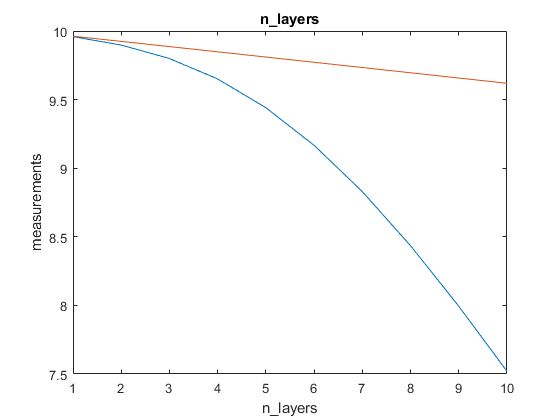

plot(x, y); xlabel('n\_layers'); ylabel('measurements'); title('n\_layers');

clear all;
TX_D = 90e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

NL = 5


TARGET_F = 20e3; % Hz
RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;


x = [1:1:40]*1e-3;
y = [];
tx = Coil.FromWindings(TX_D, TX_NT, NL, TX_AWG, TARGET_F, 100);
Bfield = Field(RX_LOC, tx);
disp(Bfield.B(3));

   3.7380e-04



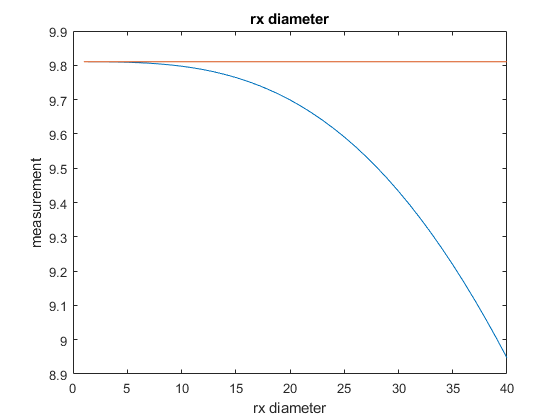

for rx_d = x
    rx = Coil.FromWindings(rx_d, RX_NT, NL, RX_AWG, TARGET_F, 0);
    [M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
    y = [y;min(measurement), max(measurement)];
end

figure();
plot(x*1000, y); xlabel('rx diameter'); ylabel('measurement'); title('rx diameter');

TX_D = 90e-3;   % coil diameter [m]
TX_D = 20e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

NL = 5


RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;


x = [5:5:100]*1e3;
y = [];
for f = x
    tx = Coil.FromWindings(TX_D, TX_NT, NL, TX_AWG, f, 0);
    rx = Coil.FromWindings(RX_D, RX_NT, NL, RX_AWG, f, 0);
    disp(tx.C);
    Bfield = Field(RX_LOC, tx);
    disp(Bfield.B(3));
    [M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, f, TX_V);
    y = [y;min(measurement), max(measurement)];
end

   1.4125e-05



   8.2471e-05



   3.5313e-06



   8.2471e-05



   1.5695e-06



   8.2471e-05



   8.8283e-07



   8.2471e-05



   5.6501e-07



   8.2471e-05



   3.9237e-07



   8.2471e-05



   2.8827e-07



   8.2471e-05



   2.2071e-07



   8.2471e-05



   1.7439e-07



   8.2471e-05



   1.4125e-07



   8.2471e-05



   1.1674e-07



   8.2471e-05



   9.8092e-08



   8.2471e-05



   8.3581e-08



   8.2471e-05



   7.2067e-08



   8.2471e-05



   6.2779e-08



   8.2471e-05



   5.5177e-08



   8.2471e-05



   4.8876e-08



   8.2471e-05



   4.3596e-08



   8.2471e-05



   3.9128e-08



   8.2471e-05



   3.5313e-08



   8.2471e-05



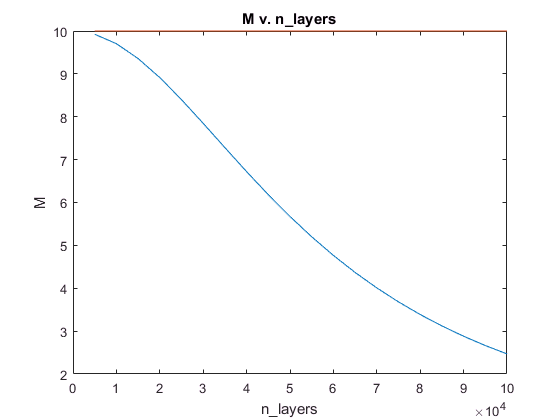


figure();
plot(x, y); xlabel('n\_layers'); ylabel('M'); title('M v. n\_layers');

clear all;
TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

NL = 5

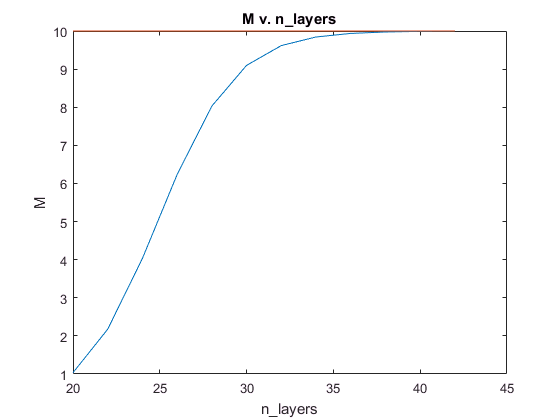


RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TARGET_F = 20e3; % Hz
TX_V = 10;


x = [20:2:42];
y = [];
for awg = x
    tx = Coil.FromWindings(TX_D, TX_NT, NL, awg, TARGET_F, 0);
    rx = Coil.FromWindings(RX_D, RX_NT, NL, awg, TARGET_F, 0);
    Bfield = Field(RX_LOC, tx);
    [M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
    y = [y;min(measurement), max(measurement)];
end

figure();
plot(x, y); xlabel('n\_layers'); ylabel('M'); title('M v. n\_layers');

clear all;
TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 20;    % # turns/layer
RX_NT = 10;
NL = 5

NL = 5

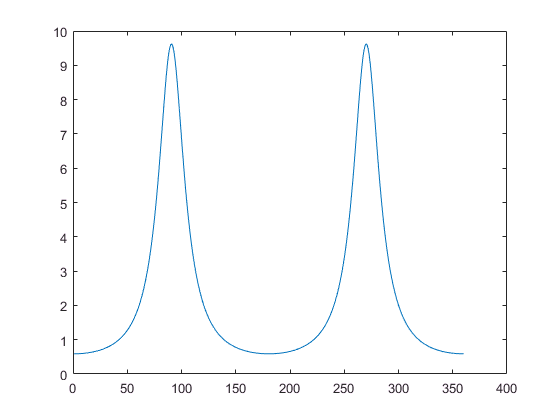


RX_LOC = [0,0,0] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TARGET_F = 200e3; % Hz
TX_V = 10;


tx = Coil.FromWindings(TX_D, TX_NT, NL, TX_AWG, TARGET_F, 100);
rx = Coil.FromWindings(RX_D, RX_NT, NL, RX_AWG, TARGET_F, 0);
Bfield = Field(RX_LOC, tx);
[M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
figure; plot(measurement);

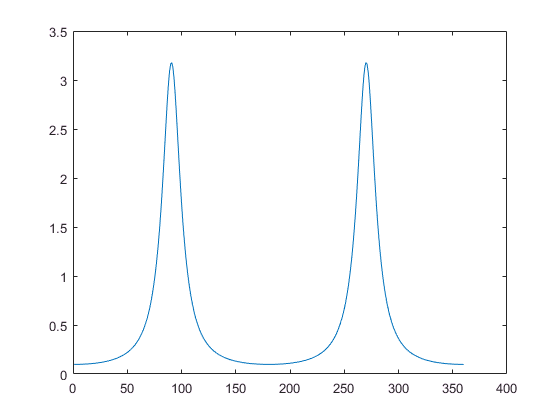

clear all;
TX_D = 100e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
RX_NL = 3;
TX_NL = 5;

RX_LOC = [0,0,0] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TARGET_F = 140e3; % Hz
TX_V = 10;


rx = Coil.FromL(RX_D, RX_NT, RX_NL, RX_AWG, TARGET_F, .11e-3, 0);
tx = Coil.FromL(TX_D, TX_NT, TX_NL, TX_AWG, TARGET_F, .11e-3, 1);
Bfield = Field(RX_LOC, tx);
[M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
figure; plot(measurement);